clear; %clc;
if isfile('composite.bmp')
     delete 'composite.bmp';
end


## Read the foreground and background images

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

fprintf('Read Images');

Read Images

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________


fg = imread('foreground.bmp')

fg = 400×800×3 uint8 array
fg(:,:,1) =

     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

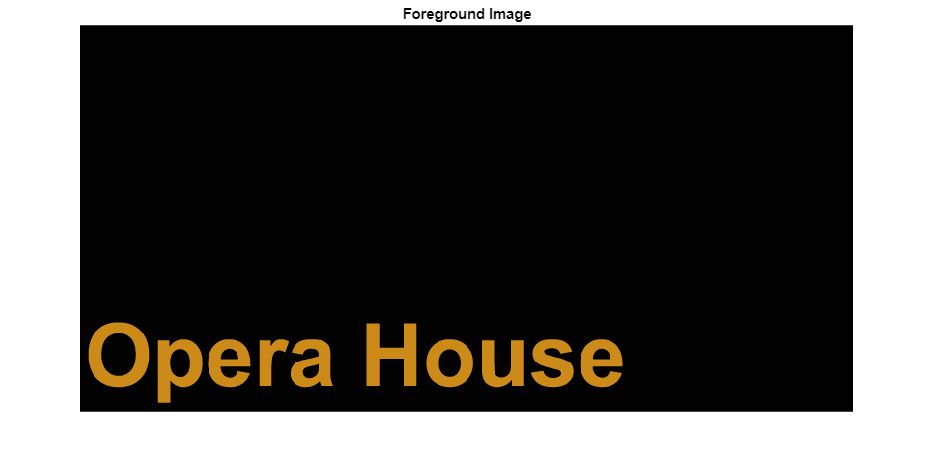

imshow(fg);
title('Foreground Image');


bg = imread('landscape.bmp')

bg = 400×800×3 uint8 array
bg(:,:,1) =

    71    69    71    72    72    74    74    73    74    73    71    70    70    71    72    71    70    72    74    72    72    70    69    70    71    69    69    68    74    78    76    73    71    72    71    70    71    69    68    70    67    68    71    72    70    70    70    70    70    70    69    69    69    71    68    67    68    67    68    70    70    71    70    69    66    67    67    66    73    71    70    70    68    68    68    69    67    67    67    67    68    67    67    68    64    65    66    68    67    67    68    68    67    66    65    66    68    68    68    67    67    65    64    65    66    67    66    65    68    66    67    66    66    69    68    66    65    66    68    69    67    67    66    65    65    67    67    68    68    68    69    68    68    66    66    66    67    65    66    67    66    68    66    67    67    66    66    67    66    66    66    67    70    70    68    64    64    63    69    69

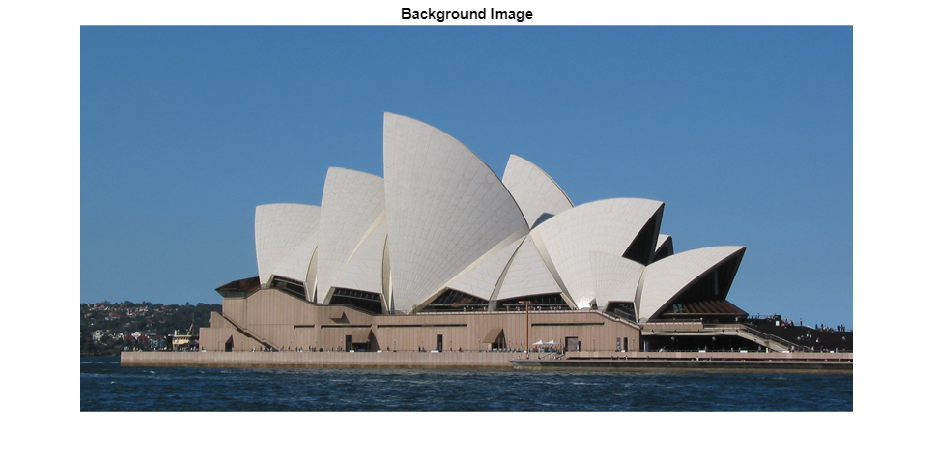

imshow(bg);
title('Background Image');

## method 1

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

fprintf('Method 1');

Method 1

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

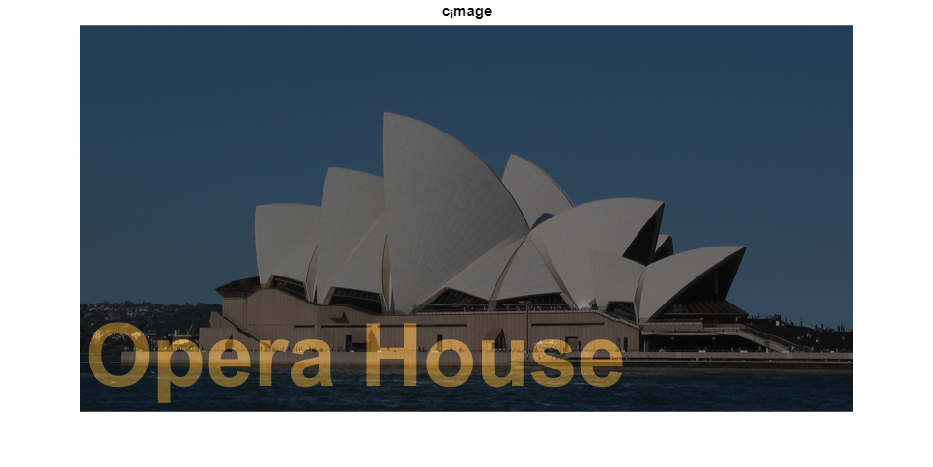


lamda = 0.5;
c_image = lamda * fg + (1 - lamda) * bg;
imshow(c_image);
title('c_image');

## method 2

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

fprintf('Method 2');

Method 2

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________


% Create a logical mask for the foreground image
% all values <10 should be ignored. black is 0
mask = fg(:,:,1) >= 10 | fg(:,:,2) >= 10 | fg(:,:,3) >= 10;
% imshow(mask);
% title('mask');

% Create a composite image by replacing the background pixels with the foreground pixels
% Use the mask to select the pixels to be replaced
[row, col, ~] = size(fg);

for r = 1:row
	for c = 1:col
		if (mask(r,c) == true)
			comp_image1(r,c,:) = fg(r,c,:);
		else
			comp_image1(r,c,:) = bg(r,c,:);
		end
	end
end

% Display the images for comparison
comp_image1

comp_image1 = 400×800×3 uint8 array
comp_image1(:,:,1) =

    71    69    71    72    72    74    74    73    74    73    71    70    70    71    72    71    70    72    74    72    72    70    69    70    71    69    69    68    74    78    76    73    71    72    71    70    71    69    68    70    67    68    71    72    70    70    70    70    70    70    69    69    69    71    68    67    68    67    68    70    70    71    70    69    66    67    67    66    73    71    70    70    68    68    68    69    67    67    67    67    68    67    67    68    64    65    66    68    67    67    68    68    67    66    65    66    68    68    68    67    67    65    64    65    66    67    66    65    68    66    67    66    66    69    68    66    65    66    68    69    67    67    66    65    65    67    67    68    68    68    69    68    68    66    66    66    67    65    66    67    66    68    66    67    67    66    66    67    66    66    66    67    70    70    68    64    64

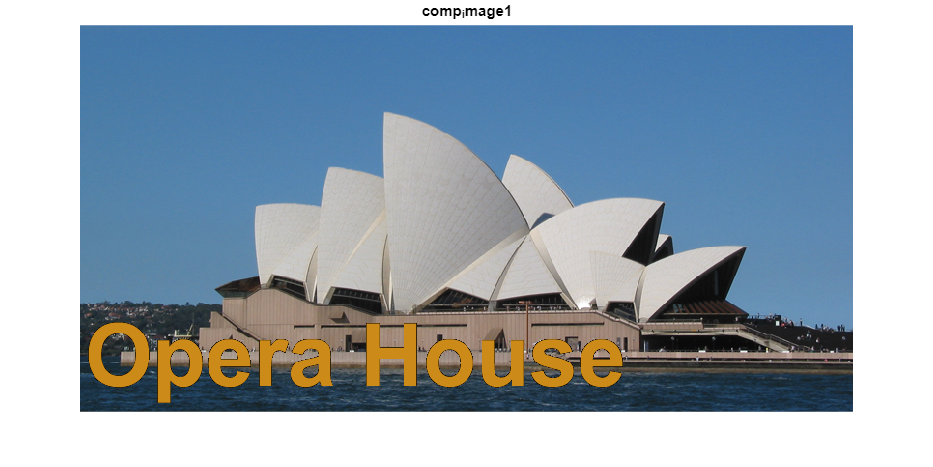

	imshow(comp_image1);
	title('comp_image1');

## method 3 : use method 1 on only mask area, thus keeping brightless levels of bg

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

fprintf('Method 3');

Method 3

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________


% Create a logical mask for the foreground image
% all values <10 should be ignored. black is 0
mask = fg(:,:,1) >= 10 | fg(:,:,2) >= 10 | fg(:,:,3) >= 10;
% imshow(mask);
% title('mask');

% Create a composite image by replacing the background pixels with the foreground pixels
% Use the mask to select the pixels to be replaced

lamda = 0.6;				% 60% of fg
[row, col, ~] = size(fg);

for r = 1:row
	for c = 1:col
		if (mask(r,c) == true)
			comp_image(r,c,:) = lamda * fg(r,c,:) + (1 - lamda) * bg(r,c,:);
		else
			comp_image(r,c,:) = bg(r,c,:);
		end
	end
end


% Display the images for comparison
comp_image

comp_image = 400×800×3 uint8 array
comp_image(:,:,1) =

    71    69    71    72    72    74    74    73    74    73    71    70    70    71    72    71    70    72    74    72    72    70    69    70    71    69    69    68    74    78    76    73    71    72    71    70    71    69    68    70    67    68    71    72    70    70    70    70    70    70    69    69    69    71    68    67    68    67    68    70    70    71    70    69    66    67    67    66    73    71    70    70    68    68    68    69    67    67    67    67    68    67    67    68    64    65    66    68    67    67    68    68    67    66    65    66    68    68    68    67    67    65    64    65    66    67    66    65    68    66    67    66    66    69    68    66    65    66    68    69    67    67    66    65    65    67    67    68    68    68    69    68    68    66    66    66    67    65    66    67    66    68    66    67    67    66    66    67    66    66    66    67    70    70    68    64    64  

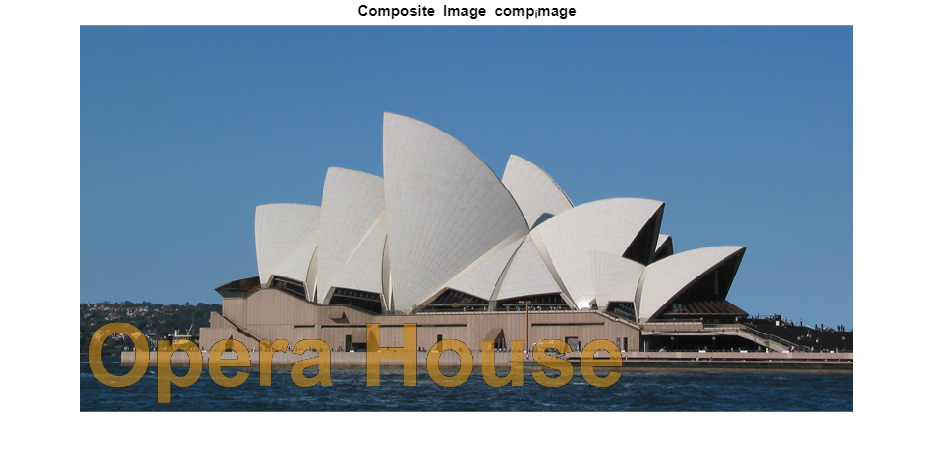

imshow(comp_image);
title('Composite Image comp_image');

## Write the output image to file 'composite.bmp'

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________

fprintf('writing to "composite.bmp"');

writing to "composite.bmp"

fprintf('________________________________________________________________________________________________________');

________________________________________________________________________________________________________


imwrite(comp_image, 'composite.bmp');